# A Branching Process Model of Complex Contagion on Random Networks: Supplementary Material

The following code reproduces figures from aforementinoed thesis.

Please do not hit 'run' as this will take quite some time. Instead run section by section.

## Working with Graphs in Matlab

Create  graph from edge list+number of nodes

G=graph([1],[2],1,3)

G =   graph with properties:

    Edges: [1×2 table]
    Nodes: [3×0 table]


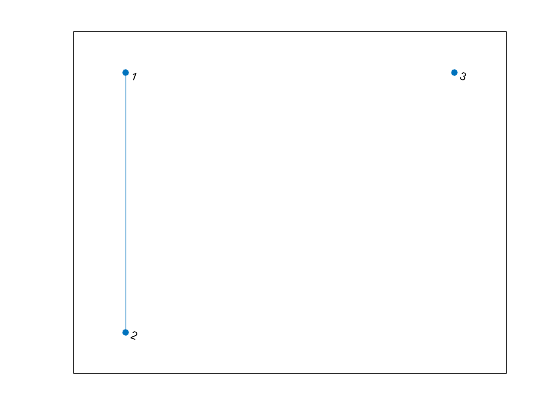

plot(G)

Create graph from Adjacency

A=[0 1 0;1 0 0;0 0 0]

A =      0     1     0
     1     0     0
     0     0     0


G=graph(A)

G =   graph with properties:

    Edges: [1×2 table]
    Nodes: [3×0 table]


G2=plot(G)

G2 =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'}
     EdgeLabel: {}
         XData: [1 1 2]
         YData: [2 1 2]
         ZData: [0 0 0]

  Show all properties


G2.NodeColor='k'

G2 =   GraphPlot with properties:

     NodeColor: [0 0 0]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'}
     EdgeLabel: {}
         XData: [1 1 2]
         YData: [2 1 2]
         ZData: [0 0 0]

  Show all properties


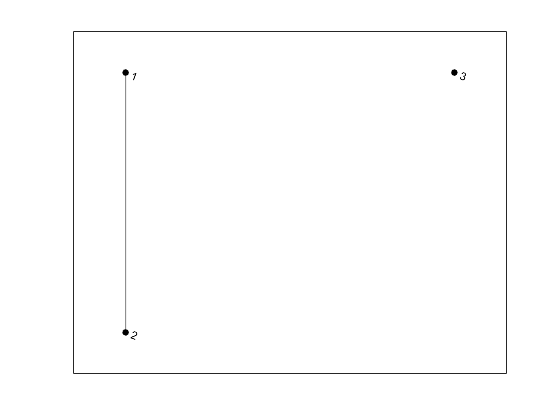

G2 =   GraphPlot with properties:

     NodeColor: [0 0 0]
    MarkerSize: 4
        Marker: 'o'
     EdgeColor: [0 0 0]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {'1'  '2'  '3'}
     EdgeLabel: {}
         XData: [1 1 2]
         YData: [2 1 2]
         ZData: [0 0 0]

  Show all properties


G2.EdgeColor='k'

Retrieve adjacency matrix from Graph object

A2=full(adjacency(G))

A2 =      0     1     0
     1     0     0
     0     0     0


Degree of each node:

deg=sum(A2)

deg =      1     1     0


meandeg=mean(deg)

meandeg = 0.6667

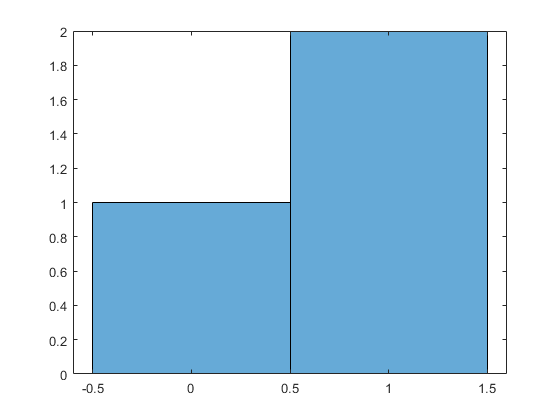

histogram(deg)

### G(n,p) method:

### G(n.m) method

### Computational Cost

clear variables

nvec=[10,10,50, 100,500, 1000,5000, 10000];
j=1;
for n=nvec
    for rep=1:10
        z=5;
        p=z/n;

        start1=tic;

        A=binornd(1,p,n,n);
        A=triu(A,1);
        G=graph(A,'upper');
        A=adjacency(G);

        elapsed1(rep)=toc(start1);

        start2=tic;

        v1=randi([1 n],1,round(z*n/2));
        v2=randi([1 n],1,round(z*n/2));
        i=1;
        while i<=n*z/2
            if v2(i)==v1(i)
                v2(i)=randi([1 n]);
            else
                i=i+1;
            end
        end
        G=graph(v1,v2,ones(1,length(v1)),n);

        A=adjacency(G);

        elapsed2(rep)=toc(start2);


    end
    time1(j)=mean(elapsed1);
    time2(j)=mean(elapsed2);

    j=j+1;
end

nvec
time1
time2
loglog(nvec(2:end),time1(2:end),nvec(2:end),time2(2:end))
%title('Comparison of computational cost between two methods')
legend('G(n,p)','G(n,m)')
xlabel('Nodes')
ylabel('Wall Time (s)')


## Watts Results

### Cascade window

clear all
n=10000
phivec=0.1:0.0025:0.26
zvec=0:0.25:16
repmax=10
for z=zvec
    z
    for phi=phivec
        for rep=1:repmax
            A=ER(n,z);
            [SUM tfin seed nb]=WattsTh(A,n,phi);
            sfin(rep)=SUM(end);
        end
        gt=sfin>n*0.2;
        result(find(zvec==z),find(phivec==phi))=sum(gt)/length(gt);
    end
end

imagesc(phivec,zvec,result)
set(gca,'YDir','normal')
colorbar
xlabel('\phi')
ylabel('z')

xlim([0.1 0.26])
ylim([0 16])

imagesc(phivec,zvec,result)
set(gca,'YDir','normal')
xline(1/4);xline(1/5);xline(1/6);xline(1/7);xline(1/8);xline(1/9);
xlabel('\phi')
ylabel('z')

xlim([0.1 0.26])
ylim([0 16])



### Cascade freq, max and mean size

clear variables
n=10000

n = 10000

phi=0.18

phi = 0.1800

zvec=0:0.2:7

zvec =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000    6.2000    6.4000    6.6000    6.8000    7.0000


repmax=1000

repmax = 1000

freq(1:length(zvec))=0

freq =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


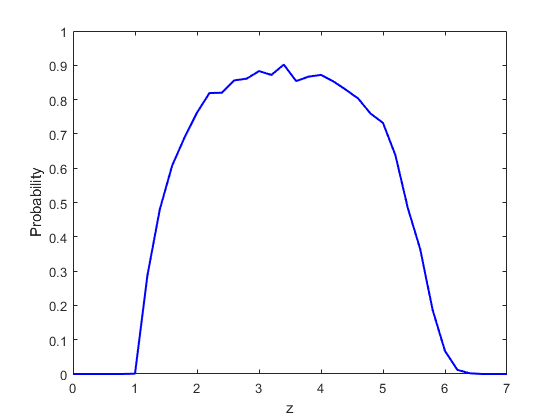

for z=zvec
    for rep=1:repmax
        A=ER(n,z);
        [SUM tfin]=WattsTh(A,n,phi);
        if SUM(end)>n*0.1
            gc(rep)=1;
        else
            gc(rep)=0;
        end
        sumfin(rep)=SUM(end);
        B=conncomp(graph(A));
        [GC,GR] = groupcounts(B') ;
        LCC(rep)=max(GC);
    end
    LCCmean(find(zvec==z))=mean(LCC);
    freq(find(zvec==z))=sum(gc)/length(gc);
    maxcasc(find(zvec==z))=max(sumfin);
    meancasc(find(zvec==z))=mean(sumfin);
end

plot(zvec,freq,'b','LineWidth',1.5)
xlabel('z')
ylabel('Probability')

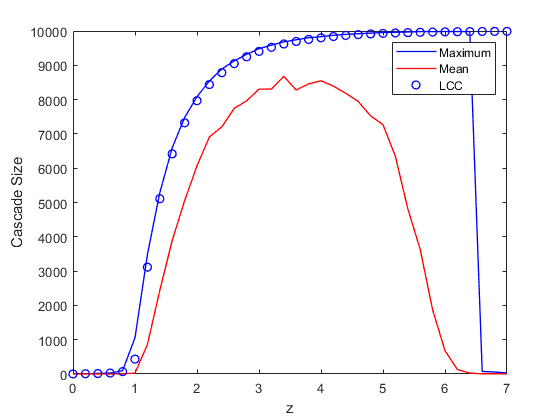


plot(zvec,maxcasc,'-b',zvec,meancasc,'-r',zvec,LCCmean,'ob','LineWidth',1)
xlabel('z')
ylabel('Cascade Size')
legend('Maximum','Mean','LCC')

## Extension of Watts results

### Heat Map and Surf plot

clear variables
n=10000

n = 10000

phi=0.18

phi = 0.1800

zvec=0:0.05:8

zvec =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500


repmax=250

repmax = 250

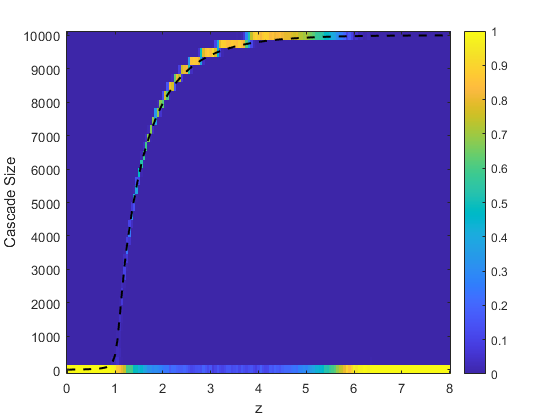


for z=zvec
z
    for rep=1:repmax
        A=ER(n,z);
        [SUM tfin]=WattsTh(A,n,phi);
        sumfin(rep)=SUM(end);

        B=conncomp(graph(A));
        [GC,GR] = groupcounts(B');
        LCC(rep)=max(GC);
    end
    [counts, bins] = histcounts(sumfin,0:50:n);
    resultvec(:,find(zvec==z))=counts;

    [counts1, bins1] = histcounts(sumfin,0:250:n);
    resultvec1(:,find(zvec==z))=counts1;

    LCCmean(find(zvec==z))=mean(LCC);
end

imagesc(zvec,0:250:n,resultvec1./repmax)
hold on
plot(zvec,LCCmean,'--k','LineWidth',1.5)
hold off
colorbar
set(gca,'YDir','normal')
xlabel('z')
ylabel('Cascade Size')

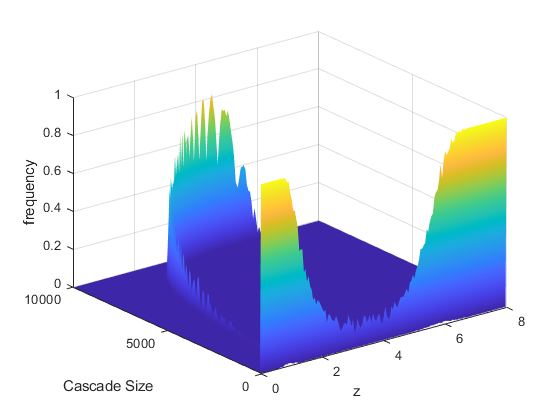


surf(zvec,25:50:n-25,resultvec./repmax)
shading interp
xlabel('z')
zlabel('frequency')
ylabel('Cascade Size')

## Surface and heatmap for BP

clear all
tmax=99

tmax = 99

repmax=250

repmax = 250

upper_limit=10000

upper_limit = 10000

zvec=0:0.05:8

zvec =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500


phi=0.18

phi = 0.1800

for z=zvec
    z

    for rep=1:repmax
        [treesize,gensize]=bpa(z,phi,upper_limit,tmax);
        genall(rep,:)=treesize;
    end
    [counts, bins] = histcounts(genall(:,end),0:50:10000);
    resultvec(:,find(zvec==z))=counts;

    [counts1, bins1] = histcounts(genall(:,end),0:250:10000);
    resultvec1(:,find(zvec==z))=counts1;
end

z = 0

z = 0.0500

z = 0.1000

z = 0.1500

z = 0.2000

z = 0.2500

z = 0.3000

z = 0.3500

z = 0.4000

z = 0.4500

z = 0.5000

z = 0.5500

z = 0.6000

z = 0.6500

z = 0.7000

z = 0.7500

z = 0.8000

z = 0.8500

z = 0.9000

z = 0.9500

z = 1

z = 1.0500

z = 1.1000

z = 1.1500

z = 1.2000

z = 1.2500

z = 1.3000

z = 1.3500

z = 1.4000

z = 1.4500

z = 1.5000

z = 1.5500

z = 1.6000

z = 1.6500

z = 1.7000

z = 1.7500

z = 1.8000

z = 1.8500

z = 1.9000

z = 1.9500

z = 2

z = 2.0500

z = 2.1000

z = 2.1500

z = 2.2000

z = 2.2500

z = 2.3000

z = 2.3500

z = 2.4000

z = 2.4500

z = 2.5000

z = 2.5500

z = 2.6000

z = 2.6500

z = 2.7000

z = 2.7500

z = 2.8000

z = 2.8500

z = 2.9000

z = 2.9500

z = 3

z = 3.0500

z = 3.1000

z = 3.1500

z = 3.2000

z = 3.2500

z = 3.3000

z = 3.3500

z = 3.4000

z = 3.4500

z = 3.5000

z = 3.5500

z = 3.6000

z = 3.6500

z = 3.7000

z = 3.7500

z = 3.8000

z = 3.8500

z = 3.9000

z = 3.9500

z = 4

z = 4.0500

z = 4.1000

z = 4.1500

z = 4.2000

z = 4.2500

z = 4.3000

z = 4.3500

z = 4.4000

z = 4.4500

z = 4.5000

z = 4.5500

z = 4.6000

z = 4.6500

z = 4.7000

z = 4.7500

z = 4.8000

z = 4.8500

z = 4.9000

z = 4.9500

z = 5

z = 5.0500

z = 5.1000

z = 5.1500

z = 5.2000

z = 5.2500

z = 5.3000

z = 5.3500

z = 5.4000

z = 5.4500

z = 5.5000

z = 5.5500

z = 5.6000

z = 5.6500

z = 5.7000

z = 5.7500

z = 5.8000

z = 5.8500

z = 5.9000

z = 5.9500

z = 6

z = 6.0500

z = 6.1000

z = 6.1500

z = 6.2000

z = 6.2500

z = 6.3000

z = 6.3500

z = 6.4000

z = 6.4500

z = 6.5000

z = 6.5500

z = 6.6000

z = 6.6500

z = 6.7000

z = 6.7500

z = 6.8000

z = 6.8500

z = 6.9000

z = 6.9500

z = 7

z = 7.0500

z = 7.1000

z = 7.1500

z = 7.2000

z = 7.2500

z = 7.3000

z = 7.3500

z = 7.4000

z = 7.4500

z = 7.5000

z = 7.5500

z = 7.6000

z = 7.6500

z = 7.7000

z = 7.7500

z = 7.8000

z = 7.8500

z = 7.9000

z = 7.9500

z = 8

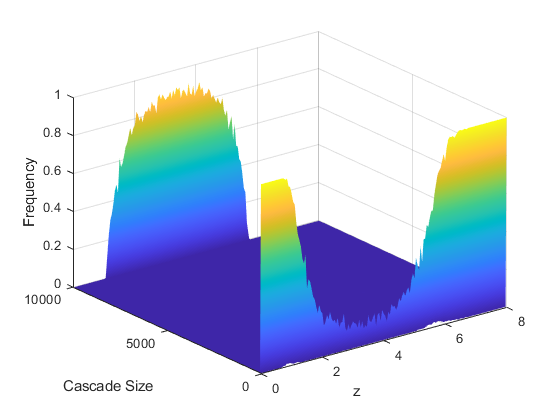




surf(zvec,25:50:10000-25,resultvec/repmax)
shading interp
xlabel('z')
zlabel('Frequency')
ylabel('Cascade Size')

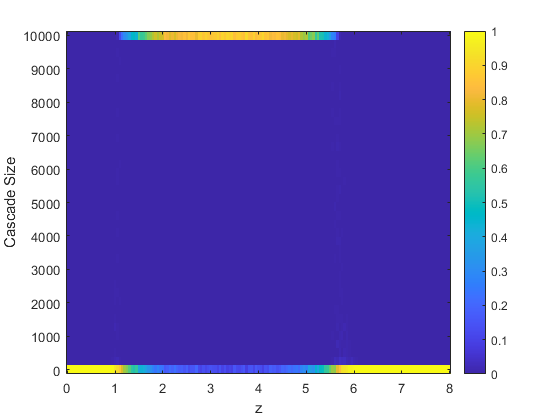


imagesc(zvec,0:250:10000,resultvec1/repmax)
set(gca,'YDir','normal')
colorbar
xlabel('z')
ylabel('Cascade Size')

## Cumulative Distributions-Watts vs. BP

clear variables
n=200000
z=1
phi=0.18
repmax=5000

for rep=1:repmax
    A=ER(n,z);
    [SUM tfin seed nb]=WattsTh(A,n,phi);
    sumfin(rep)=SUM(end);
end

for m=1:10000
    cumudistWatts(m)=sum(sumfin>=m);
end


tmax=99;
for rep=1:repmax

    gen=1;
    gen(2:tmax)=0;
    CoA=poissrnd(z);
    for t=2:tmax
        if max(gen)>10000
            gen(t:end)=10000;
            break
        else
        end
        k=poissrnd(z,CoA,1);
        k=k+1;
        gen(t)=gen(t-1)+sum(k<=5);
        CoA=sum(nonzeros(k.*(k<=5))-1);

    end
    sumfinbp(rep)=gen(end);
end

for m=1:10000
    cumudistBP(m)=sum(sumfinbp>=m);
end

loglog(1:10000,cumudistBP,1:10000,cumudistWatts)
ylim([1 repmax])
xlim([1 10000])
legend('Branching Process','Watts','Location','SouthWest')



## Restricted Watts Model

clear variables
n=10000
z=5.76
phi=0.18
repmax=1000

for rep=1:repmax
    A=ER(n,z);
    [SUM tfin seed nb]=WattsThRestricted(A,n,phi);
    sumfin(rep)=SUM(end);
end

for m=1:n
    cumudistWatts(m)=sum(sumfin>=m);
end


tmax=99;
for rep=1:repmax

    gen=1;
    gen(2:tmax)=0;
    CoA=poissrnd(z);
    for t=2:tmax
        if max(gen)>10000
            gen(t:end)=10000;
            break
        else
        end
        k=poissrnd(z,CoA,1);
        k=k+1;
        gen(t)=gen(t-1)+sum(k<=5);
        CoA=sum(nonzeros(k.*(k<=5))-1);

    end
    sumfinbp(rep)=gen(end);
end

for m=1:n
    cumudistBP(m)=sum(sumfinbp>=m);
end

loglog(1:n,cumudistBP,1:n,cumudistWatts)
ylim([1 repmax])
xlim([1 n])
legend('Branching Process','Watts','Location','SouthWest')

## Other

clear variables
n=10
z=4
A=ER(n,z)
G=graph(A)
G3=plot(G)
G3.NodeColor='k'
G3.EdgeColor='k'


A=[0 1 0;1 0 0;0 0 0]
G=graph(A)
G4=plot(G)
G4.NodeColor='k'
G4.EdgeColor='k'

### Branching Number

clear variables
zvec=0.5:0.1:7

zvec =     0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000


phi=0.18

phi = 0.1800

upper_limit=10000

upper_limit = 10000

repmax=1000;
tmax=20;
for z=zvec
    gensizeall=zeros(repmax,tmax);
    z
    for rep=1:repmax
        [treesize,gensize]=bpa(z,phi,upper_limit,tmax);
        sumfinbp(rep)=treesize(end);
        gensizeall(rep,:)=gensize;
    end
    s=sum(gensizeall);
    branchingnumber=s(2:end)./s(1:end-1);
    BN(find(zvec==z))=mean(branchingnumber(2:10));
end

z = 0.5000

z = 0.6000

z = 0.7000

z = 0.8000

z = 0.9000

z = 1

z = 1.1000

z = 1.2000

z = 1.3000

z = 1.4000

z = 1.5000

z = 1.6000

z = 1.7000

z = 1.8000

z = 1.9000

z = 2

z = 2.1000

z = 2.2000

z = 2.3000

z = 2.4000

z = 2.5000

z = 2.6000

z = 2.7000

z = 2.8000

z = 2.9000

z = 3

z = 3.1000

z = 3.2000

z = 3.3000

z = 3.4000

z = 3.5000

z = 3.6000



%To plot single value of z
plot(1:length(branchingnumber),branchingnumber,'LineWidth','1.5')
ylabel('Branching Number')
xlabel('Generation')



%To plot range of z
plot(zvec,BN)
ylabel('Branching Number')
xlabel('z')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Theoretical Branching Number

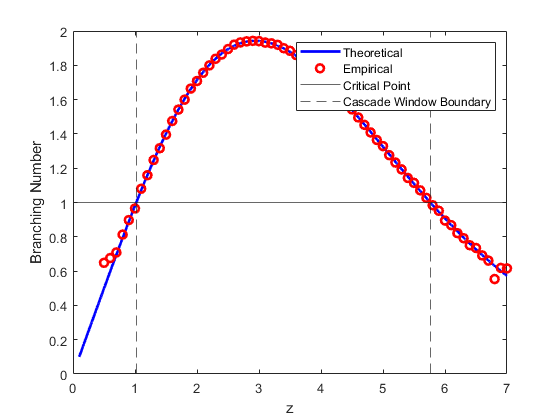

k=1:20;
zvec2=0.1:0.001:7;
T=0.18;
k2=1:1/T;
F=k<1/T;

for z=zvec2
    C(find(zvec2==z))=sum(k.*(k-1)./z.*poisspdf(k,z).*F);
end
plot(zvec2,C,'-b',zvec,BN,'or','LineWidth',2)
yline(1);xline([1.02 5.76],'LineStyle','--');
xlabel('z')
ylabel('Branching Number')
legend('Theoretical','Empirical','Critical Point','Cascade Window Boundary')

#### f''(1) and f'(1) Calculation

clear  variables
zvec=1

zvec = 1

repmax=10000

repmax = 10000

phi=0.18

phi = 0.1800

upper_limit=10000

upper_limit = 10000

tmax=21

tmax = 21

for z=zvec
gensizeall=zeros(repmax,tmax);
    z
    for rep=1:repmax
        [treesize,gensize]=bpa(z,phi,upper_limit,tmax);
        sumfinbp(rep)=treesize(end);
        gensizeall(rep,:)=gensize;
    end

    %f'(1) calc
    s=sum(gensizeall);
    branchingnumber=s(2:end)./s(1:end-1);
    
    BN(find(zvec==z))=mean(branchingnumber(2:10));
    
    %%%%f''calc
    v=var(gensizeall);
    fpp=v+BN(zvec==z)^2-BN(zvec==z);
    fpp2=fpp(3:end)./fpp(2:end-1);
    f2(zvec==z)=mean(fpp2(2:10));
end

z = 1

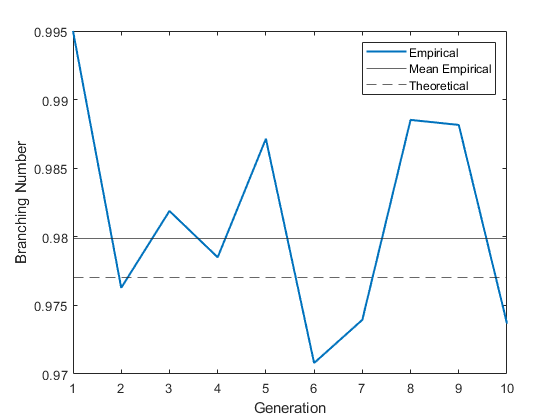

%To plot single z value:
plot(1:10,branchingnumber(1:10),'LineWidth',1.5)
ylabel('Branching Number')
xlabel('Generation')
yline(BN,'LineStyle','-')
yline(0.977,'Linestyle','- -')
legend('Empirical','Mean Empirical','Theoretical')

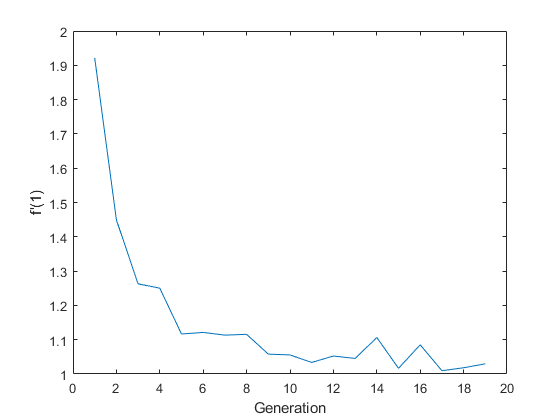


plot(1:length(fpp2),fpp2)
ylabel('f''(1)')
xlabel('Generation')

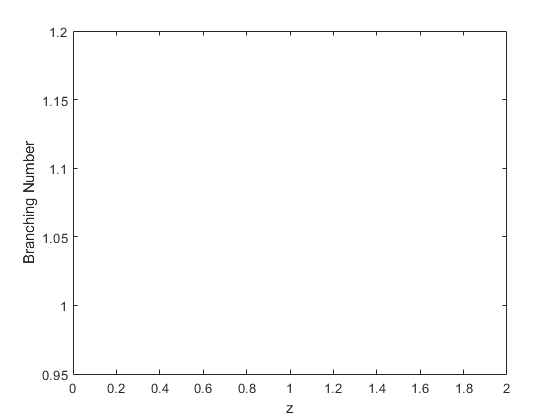

%To plot range of z:
plot(zvec,BN,zvec,f2)
ylabel('Branching Number')
xlabel('z')

#### Critical Branching Process

clear variables

n=10000

n = 10000

z=1

z = 1

repmax=10000

repmax = 10000

phi=0.18

phi = 0.1800


for rep=1:repmax
    A=ER(n,z);
    [SUM, tfin]=WattsTh(A,n,phi);
    sfin(rep)=SUM(end);
end

for m=1:n
    PDF(m)=sum(sfin==m)./repmax;
end
intpdf=sum(PDF)

intpdf = 1.0000

fpp=1

fpp = 1

B=(0.5*fpp*pi)^(-1/2)./2;
o=1:100;
p=B.*o.^(-3/2);
sum_p=sum(p)

sum_p = 0.9626

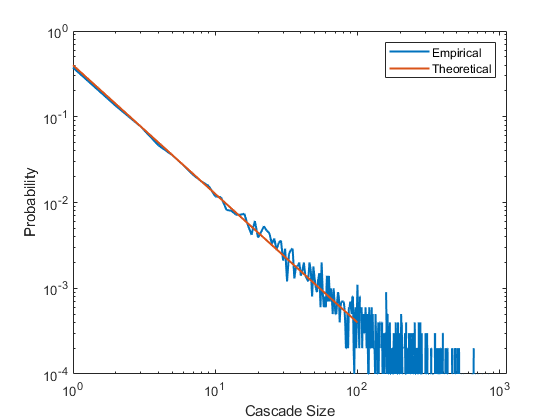

figure(2)
loglog(1:n,PDF,o,p,'LineWidth',1.5)
xlabel('Cascade Size')
ylabel('Probability')
legend('Empirical','Theoretical')

#### Near-critical Branching Process z=1.1

clear variables

n=10000

n = 10000

z=1.1

z = 1.1000

repmax=5000

repmax = 5000

phi=0.18

phi = 0.1800


for rep=1:repmax
    A=ER(n,z);
    [SUM, tfin]=WattsTh(A,n,phi);
    sfin(rep)=SUM(end);
end

for m=1:n
    PDF(m)=sum(sfin==m)./repmax;
end
intpdf=sum(PDF)

intpdf = 1.0000

fpp=1.34

fpp = 1.3400

B=(0.5*fpp*pi)^(-1/2)./2;
kappa=(2*fpp)./(z-1).^2;
o=1:n;
p=B.*o.^(-3/2).*exp(-o./kappa);
sum_p=sum(p)

sum_p = 0.8276

p(n)=(1-sum_p)

p =     0.3434    0.1209    0.0656    0.0424    0.0303    0.0229    0.0181    0.0148    0.0123    0.0105    0.0091    0.0079    0.0070    0.0062    0.0056    0.0051    0.0046    0.0042    0.0039    0.0036    0.0033    0.0031    0.0029    0.0027    0.0025    0.0024    0.0022    0.0021    0.0020    0.0019    0.0018    0.0017    0.0016    0.0015    0.0015    0.0014    0.0013    0.0013    0.0012    0.0012    0.0011    0.0011    0.0010    0.0010    0.0010    0.0009    0.0009    0.0009    0.0008    0.0008


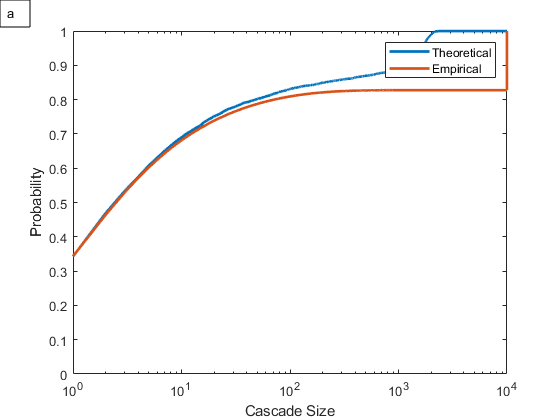

figure(2)
plot(1:n,cumsum(PDF),o,cumsum(p),'LineWidth',2)
set(gca, 'XScale', 'log')
ylim([0 1])
xlabel('Cascade Size')
ylabel('Probability')
legend('Theoretical','Empirical')
dim = [0 0 1 1];
annotation('textbox',dim,'String','a','FitBoxToText','on');

#### Near-critical Branching Process: z=2

clear variables

n=10000

n = 10000

z=2

z = 2

repmax=5000

repmax = 5000

phi=0.18

phi = 0.1800


for rep=1:repmax
    A=ER(n,z);
    [SUM, tfin]=WattsTh(A,n,phi);
    sfin(rep)=SUM(end);
end

for m=1:n
    PDF(m)=sum(sfin==m)./repmax;
end
intpdf=sum(PDF)

intpdf = 1

fpp=3

fpp = 3

B=(0.5*fpp*pi)^(-1/2)./2;
kappa=(2*fpp)./(z-1).^2;
o=1:n;
p=B.*o.^(-3/2).*exp(-o./kappa);
sum_p=sum(p)

sum_p = 0.3238

p(n)=(1-sum_p)

p =     0.1950    0.0583    0.0269    0.0148    0.0090    0.0058    0.0039    0.0027    0.0019    0.0014    0.0010    0.0007    0.0006    0.0004    0.0003    0.0003    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


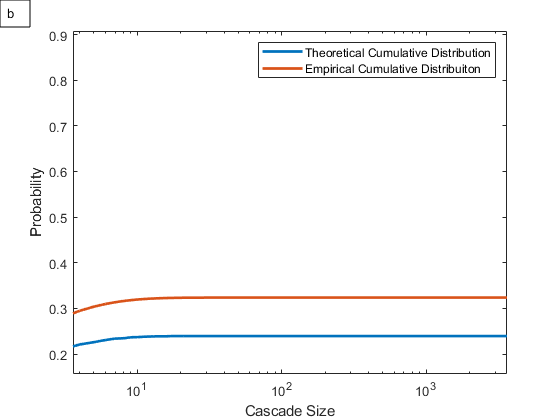

figure(2)
plot(1:n,cumsum(PDF),o,cumsum(p),'LineWidth',2)
set(gca, 'XScale', 'log')
ylim([0 1])
xlabel('Cascade Size')
ylabel('Probability')
legend('Theoretical','Empirical')
dim = [0 0 1 1];
annotation('textbox',dim,'String','b','FitBoxToText','on');

## Functions

function[SUM, tfin]=WattsTh(A,n,phi)
%Randomly assign seed node
S=zeros(n,1);seed=[randi(n,1,1)];
S(seed)=1;
%Assign thresholds from distribution (heterogeneous) or constant
%(homoegeneous) as in this case
T=ones(n,1)*phi;
%We wish to iterate until dynamics reach steady state ie no new adopters in
%a generation, so define conditions for loop as new sum of adopters being
%greater than sum of adopters from last iteration
Snew=1;Sold=0;t=0;

while Snew>Sold
    AN=A*S;         %active neighbors
    TN=sum(A);      %total neighbours
    Supd=AN./TN'> T;%boolean operation for vulnerability conditon
    S=(S+Supd)>0;   %boolean operation to remove duplicate active nodes, or combine active nodes from previous generation with current generation
    Sold=Snew;      %update values for next time step
    Snew=sum(S);    %update values for next time step
    t=t+1;          %increase time index by 1
    SUM(t)=sum(S);  %assign total number of active nodes at time=t
end
tfin=t;             %total time to steady state
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function[SUM, tfin, seed, nb]=WattsThRestricted(A,n,phi)

%Randomly assign seed node
S=zeros(n,1);seed=[randi(n,1,1)];
S(seed)=1;
%Assign thresholds from distribution (heterogeneous) or constant
%(homoegeneous) as in this case
T=ones(n,1)*phi;
%We wish to iterate until dynamics reach steady state ie no new adopters in
%a generation, so define conditions for loop as new sum of adopters being
%greater than sum of adopters from last iteration
Snew=1;Sold=0;t=0;

while Snew>Sold
    AN=A*S;         %active neighbors
    TN=sum(A);      %total neighbours
    Supd=(AN>0)./TN'> T;%boolean operation for vulnerability conditon
    S=(S+Supd)>0;   %boolean operation to remove duplicate active nodes, or combine active nodes from previous generation with current generation
    Sold=Snew;      %update values for next time step
    Snew=sum(S);    %update values for next time step
    t=t+1;          %increase time index by 1
    SUM(t)=sum(S);  %assign total number of active nodes at time=t
end
tfin=t;             %total time to steady state
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [A]=ER(n,z)
%Create two vectors of length 0.5*z*n uniformly from all possible nodes
v1=randi([1 n],1,round(z*n/2));
v2=randi([1 n],1,round(z*n/2));
%Loop to remove self loops-not strictly neccessary but reasonably low cost
i=1;
while i<=n*z/2
    if v2(i)==v1(i)
        v2(i)=randi([1 n]);
    else
        i=i+1;
    end
end
%Create graph from node lists v1 and v2
G=graph(v1,v2,ones(1,length(v1)),n);
A=adjacency(G);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [treesize,gensize]=bpa(z,phi,upper_limit,tmax)
T=1/phi;  %Convert homogeneous threshold to limit for highest accessible node degree
%Defining generation 1 and vector sizes
gensize=1; gensize(2:tmax)=0;
treesize=1; treesize(2:tmax)=0;
%Exterior node offspring distribution
CoA=poissrnd(z);%CoA=children of active ndoes
%loop in time for interior nodes
for t=2:tmax
    if max(treesize)>upper_limit
        treesize(t:end)=upper_limit;
        break
    else
    end
    %Excess degree distribution
    k=poissrnd(z,CoA,1); k=k+1;
    %Tree size: tree size up to previous generation+current generation
    treesize(t)=treesize(t-1)+sum(k<T);
    %Children of active nodes for current generation
    CoA=sum(nonzeros(k.*(k<T))-1);%Boolean restricts contribution to nodes below threshold
    gensize(t)=sum(k<T);
end
end